# Numerical Differentitation

La diferenciación númerica aproxima el valor de una de la derivada de una función utilizando una serie de puntos, la cual puede ser dada o se pueden obtener de la misma función pasada como parametro.

    En este caso usaremos la segunda opción, es decir, definiremos una función y=f(x)

%f = @(x) cosh(x);   % in-line function declaration

El método utilizado para aproximar será el de las series de Taylor. Esto tiene como consecuencia que existan dos fuentes de error inevitables:

- redondeo de la maquina (debido a la precisión limitada)

- error de truncamiento de las series de taylor (no planeamos resolverlas hasta converger, sino truncarlas en cierto punto)

## Taylor series

Por definición, la aproximación con una serie de taylor par auna función $$f(x)$$ alderedor del punto $$a$$ es:


$$f\left(x\right)\;\approx f\left(a\right)+\frac{f^{\prime } \left(a\right)}{1!}\left(x-a\right)+\frac{f^{\prime \prime } \left(a\right)}{2!}{\left(x-a\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(a\right)}{n!}{\left(x-a\right)}^n$$


Ahora, si aproximamos en funcion de $x+h$ alrededor de un punto $x$


$$f\left(x+h\right)\approx f\left(x\right)+\frac{f^{\prime } \left(x\right)}{1!}\left(h\right)+\frac{f^{\prime \prime } \left(x\right)}{2!}{\left(h\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x\right)}{n!}{\left(h\right)}^n$$


## First derivative

Resolviendo varias funciones de taylor, podemos despejar la primera derivada de x de la ecuacion resultante al substraer de la serie de f(x+h) alrededor de x de la serie de f(x-h) alrededor de x.


$$f\left(x+h\right)-f\left(x-h\right)\approx 2\left\lbrack {\textrm{hf}}^{\prime } \left(x\right)+\frac{h^3 }{3!}f^{\prime \prime \prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right\rbrack$$


despejando para ${f}'(x)$


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{1}{2h}\left(\frac{h^3 }{3!}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{h^2 }{6}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)-\ldotp \ldotp \ldotp$$


por lo que si fijamos x y variamos h para identificar la precision de la aproximación, podemos asumir que el error de truncamiento se comporta como $h^2$. Es decir.


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$

$$$+ \mathcal{O}(h^2)$$$


Ya que *h *es la mayoria de las veces menor a 1, a mayor grado de exponente en *h* , mejor es la aproximación.

En el caso de querer mejorar la precisión, deberiamos calcular más series de Taylor como funciones de $x\pm (n)h$ y cancelaras entre sí.

## Generalization

Usando el método anteriormente descrito, llegamos a tres formas distintas, las aproximaciones centradas, hacia adelante y hacia atrás. Analizaremos la primera y la segunda derivada de las funciones $f(x) = e^{-x}$  y $g(x) = \ln{x}$

format long
syms g(x) f(x);
f(x)=exp(-x) 

$$f(x) = {\mathrm{e}}^{-x}$$

func1 = @(x)  exp(-x);
%f(x)=log(x)
%func2 = @(x) log(x);

c=0.5;
i = 1:30;
arr = @(x) double(power(c,x));

hs = arr(i)

hs =    0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000   0.015625000000000   0.007812500000000   0.003906250000000   0.001953125000000   0.000976562500000   0.000488281250000   0.000244140625000   0.000122070312500   0.000061035156250   0.000030517578125   0.000015258789063   0.000007629394531   0.000003814697266   0.000001907348633   0.000000953674316   0.000000476837158   0.000000238418579   0.000000119209290   0.000000059604645   0.000000029802322   0.000000014901161   0.000000007450581   0.000000003725290   0.000000001862645   0.000000000931323


x=2

x =      2


## Central finite difference

Las aproximaciones pueden realizarse de forma "centralizada", este nombre proviene de la necesidad de calcular los puntos $f\left(x+h\right)$ y $f\left(x-h\right)$ para una x que se encuentra en el centro de estos dos. 

    Usaremos las dos siguientes formulas para aproximar la primera y segunda derivada de las funciones.


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$

$$$+ \mathcal{O}(h^2)$$$



$$f^{\prime \prime } \left(x\right)\approx \frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$$

$$$+ \mathcal{O}(h^2)$$$


%calcular valor real
df      = diff(f)
df_x    = double(df(x))

$$df(x) = -{\mathrm{e}}^{-x}$$

d2f     = diff(f,2)

df_x =     -329/2431  


df2_x   = double(d2f(x))

$$d2f(x) = {\mathrm{e}}^{-x}$$

df2_x =      329/2431  


error = zeros([2,length(hs)])


error =        0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       
       0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


j=1;
for h = hs
    ap1 = firstCenteredDerivative(func1,x,h);
    ap2 = secondCenteredDerivative(func1,x,h);
    error(1,j)=abs(ap1/df_x -1);
    error(2,j)=abs(ap2/df2_x -1);
    j = j+1;
end


figure;
loglog(hs,error)
hold on
%semilogx(hs,error)
%semilogx(hs,error(2,:))
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o")
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o")
set(gca,'XDir','reverse')
xlabel("step size h")
ylabel("Relative Error (%)")


%optimal h for f''(x)
dft = diff(f,4)
m = double(dft(x))

$$dft(x) = {\mathrm{e}}^{-x}$$

m2 = power((3*eps)/m,1/4)

m =      329/2431  


ym2 = abs(secondCenteredDerivative(func1,x,m2)/df2_x -1)

m2 =       38/143465


loglog(m2,ym2,"r *")

ym2 =        1/1625439534



%optimal h for f'(x)
dft = diff(f,3)
m = abs(double(dft(x)))

$$dft(x) = -{\mathrm{e}}^{-x}$$

m2 = power((3*eps)/m,1/3)

m =      329/2431  


ym2 = abs(firstCenteredDerivative(func1,x,m2)/df_x -1)

m2 =        4/235149


grid

ym2 =        1/19071170192


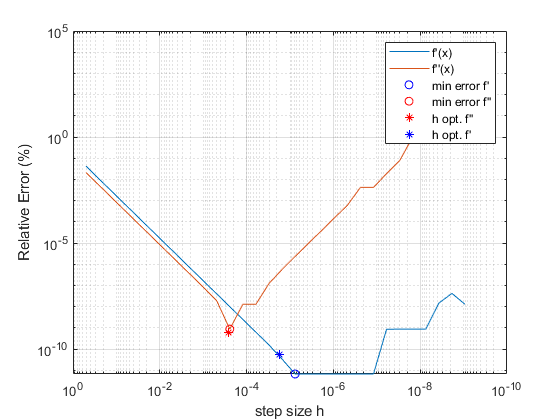

loglog(m2,ym2,"b *")
legend("f'(x)","f''(x)","min error f'","min error f''" ,"h opt. f''","h opt. f'")

## m-th derivative with precision n 

n=4;m=2;
n_coefs=2*floor((m+1)/2)-1+n; p=(n_coefs-1)/2;
% Solve system A*w = b
A=power(-p:p,(0:2*p)'); b=zeros(2*p+1,1); b(m+1)=factorial(m); coefs=A\b %inv(A)*b

% Round elements near values close to machine-epsilon to zero

coefs =   -0.083333333333333
   1.333333333333333
  -2.500000000000000
   1.333333333333333
  -0.083333333333333


coefs = coefs.*not(abs(coefs)<2000*eps);
format rational;
coefs

coefs =       -1/12    
       4/3     
      -5/2     
       4/3     
      -1/12    
